# 数字图像处理 作业6 (4/16)

阮泉源 201930033629

## 自适应均值滤波

读取图片

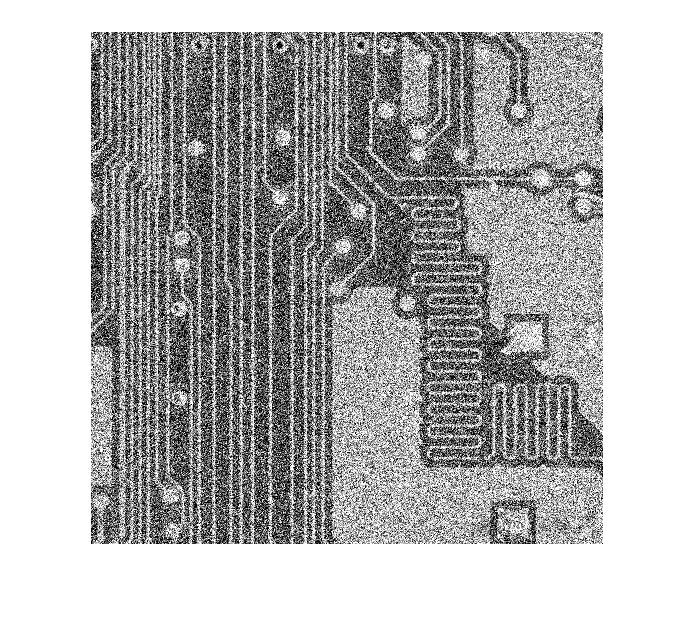

im_circuit = imread('circuit.jpg');
im_circuit = rgb2gray(im_circuit);
im_circuit = im2double(im_circuit);
im_noise = imnoise(im_circuit, 'gaussian', 0, 0.1);
figure;
imshow(im_noise);

设噪声的方差为$\sigma_{\eta \;}^2$，局部均值为$m_L$，局部方差为$\sigma {\;}_L^2$。局部区域的大小为$N\times N$，假设在图片中存在有局部区域大小的相对平坦区域，此时有$\sigma_{\eta \;}^2 \le \sigma {\;}_L^2$存在。

因此对图片进行遍历采样，获取最小的区域方差假设为噪声方差，为避免干扰，选择最小方差的0.5%~1%的平均值作为噪声方差的估计。

N = 7;
[w, h] = size(im_noise);

win = floor(N/2);

% real_var = var(reshape(im_noise-im_circuit, 1, []));

im_sigma_L = zeros(floor(w/N), floor(h/N));

for i = 1:floor(w/N)
    for j = 1:floor(h/N)
        sub_im = im_noise(1+(i-1)*N:1+i*N, 1+(j-1)*N:1+j*N);
        sub_im = reshape(sub_im, 1, []);
        im_sigma_L(i, j) = var(sub_im);
    end
end

im_sigma_L = reshape(im_sigma_L, 1, []);
n = length(im_sigma_L);

im_sigma_L = sort(im_sigma_L);
sigma_eta = im_sigma_L(floor(n/200):floor(n/100));
sigma_eta = mean(sigma_eta);

最后对图片进行处理，根据$\hat{\;f} \left(x,y\right)=g\left(x,y\right)-\frac{\sigma_{\eta \;}^2 }{\sigma_L^2 \;}\left(g\left(x,y\right)-m_L \right)$，得到原始图片的估计。

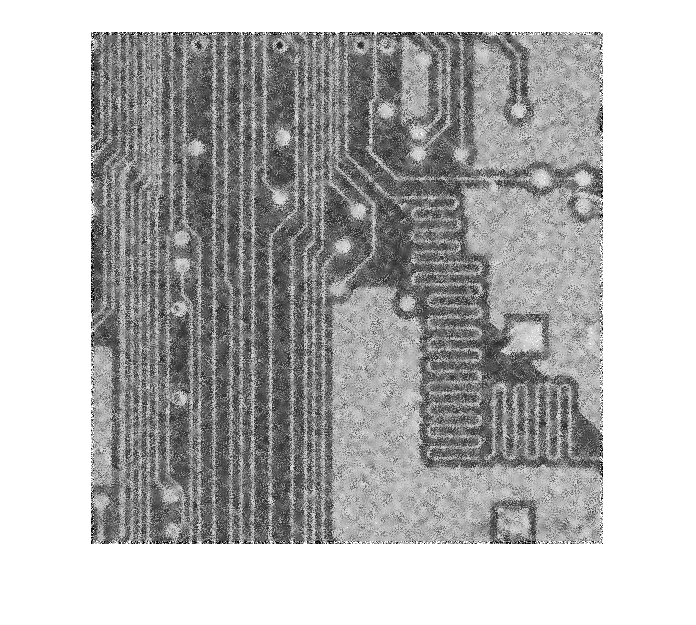

im_out = im_noise;

for i = 1+win:w-win
    for j = 1+win:h-win
        sub_im = im_noise(i-win:i+win, j-win:j+win);
        sub_im = reshape(sub_im, 1, []); 
        m_L = mean(sub_im);
        sigma_L = var(sub_im-m_L);
        im_out(i,j) = im_noise(i,j)*(1-sigma_eta/sigma_L)+m_L*(sigma_eta/sigma_L);
    end
end
figure;
imshow(im_out)

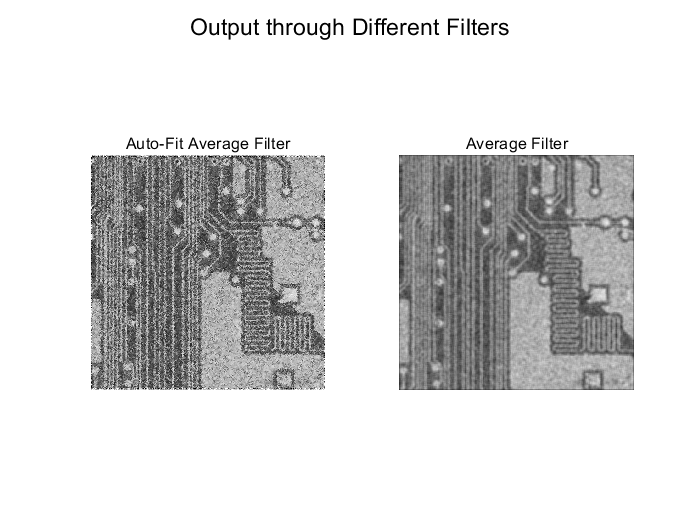

im_mean = conv2(im_noise, ones(N, N)/(N*N));
im_mean = im_mean(win+1:win+w, win+1:win+h);

figure;
subplot(1,2,1)
imshow(im_out)
title('Auto-Fit Average Filter')
subplot(1,2,2)
imshow(im_mean)
title('Average Filter')
suptitle('Output through Different Filters')

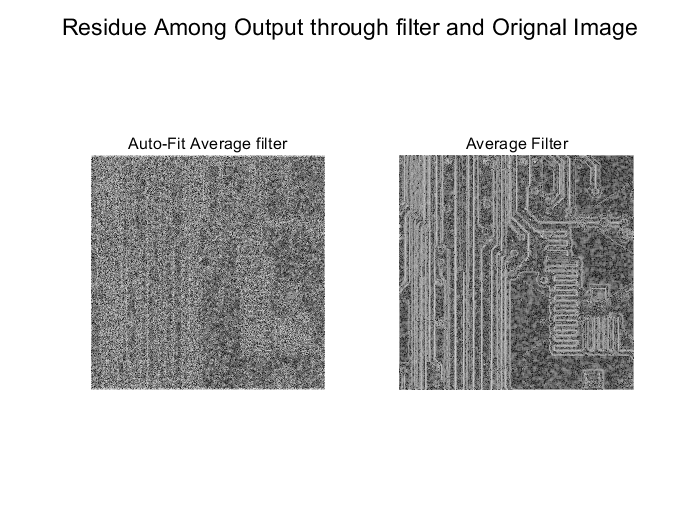

figure;
subplot(1,2,1)
imshow(abs(im_circuit-im_out).^0.3)
title('noise image')
title('Auto-Fit Average filter')
subplot(1,2,2)
imshow(abs(im_circuit-im_mean).^0.3)
title('Average Filter')
suptitle('Residue Among Output through filter and Orignal Image')

遇到的问题：对噪声的估计不太明确。

解决方法：通过多个值进行估计。

## 结果分析

可以看到，自适应均值滤波器的效果比普通均值滤波器要更好，清晰度更高以及相对于原始图片的残差更小。